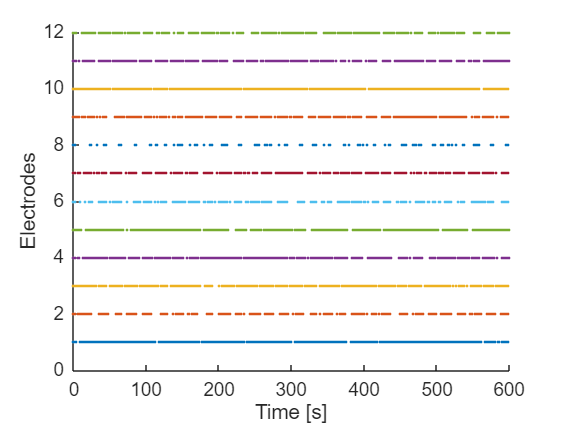

% clear all
% clc
% close all


Strings = [['012'],
           ['013'],
           ['021'],
           ['022'],
           ['023'],
           ['024'],
           ['031'],
           ['032'],
           ['033'],
           ['034'],
           ['042'],
           ['043']];


% Extract data
cd 'E:\Rec Linda\Dup15\Batch2\DIV35_6867\20240625_Control_00\Well_23\well_23_PeakDetectionMAT_PLP2ms_RP2ms\ptrain_Control00_Well23'
% cd 'E:\Rec Linda\Dup15\Batch1\DIV35_5337\20240625_Group_02\Well_14\well_14_PeakDetectionMAT_PLP2ms_RP2ms\ptrain_Group02_Well14'

base = 'ptrain_Control00_Well23_';
% base = 'ptrain_Group02_Well14_';
Well = '11';
t_rec = 600; % [s] Recording time
fs = 10000;
T_max = t_rec * fs;


data = cell(length(Strings),1);

for i = 1:length(Strings)

        x = load([base,Strings(i,:)]).peak_train;
        lendata = length(x);
        % REMOVE HALFSIZE IN THE MAIN SIM
        [Spk_timing,col,Spk_amplitude] = find(x);
        data{i} = Spk_timing;


end


% Extract peak trains

halfsize = floor(lendata/2);


figure()

for i = 1:length(Strings)

    data_timings = data{i};

    data_plot = ones(length(data_timings),1)*i;

    scatter(data_timings/fs,data_plot,'SizeData',15,'Marker','.')
    hold on


    
end
xlabel('Time [s]')
ylabel('Electrodes')
hold off

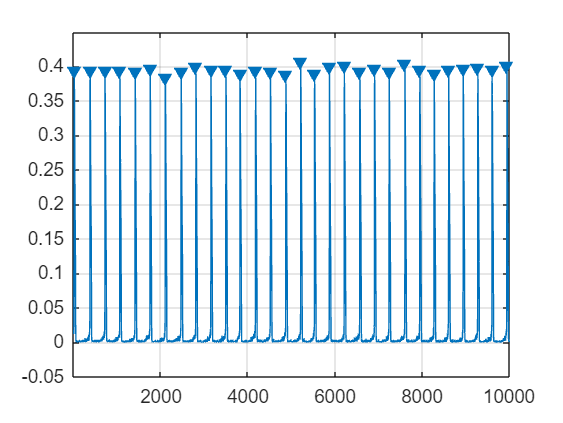


w_size = 0.12;  % [s] 12
overlap = 0.06;  % [s]

[Cumulative,t_vec,step_s] = Rect_window(fs,w_size, overlap,data,T_max);


Mean_IFR = mean(Cumulative); 
STD_IFR = std(Cumulative);
plot_MFR = ones(length(t_vec),1)*Mean_IFR;
plot_MFR_STD_plus = ones(length(t_vec),1)*STD_IFR;
plot_MFR_STD_minus = ones(length(t_vec),1)*(-STD_IFR);
[~,idx] = findpeaks(Cumulative,"MinPeakHeight",Mean_IFR+STD_IFR,MinPeakDistance=3 * fs / step_s);
NB_T = t_vec(idx);

figure()
findpeaks(Cumulative,"MinPeakHeight",Mean_IFR+STD_IFR,MinPeakDistance=3* fs / step_s)

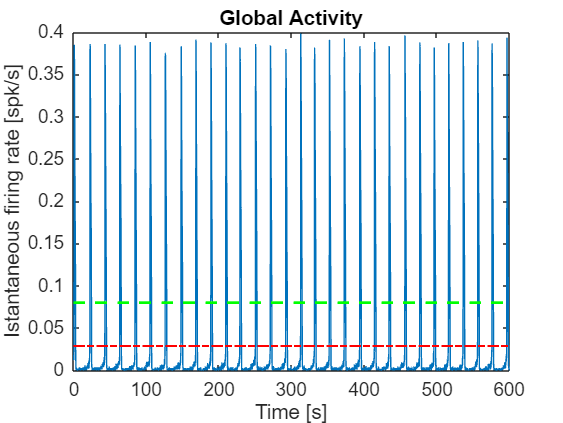


figure()
title('Global Activity')
plot(t_vec/fs,Cumulative)
hold on
plot(t_vec/fs,plot_MFR,'LineStyle','-.','Color','r','LineWidth',1.5)
plot(t_vec/fs,plot_MFR_STD_plus,'LineStyle','--','Color','g','LineWidth',1.5)
% plot(t_vec/fs,plot_MFR_STD_minus,'LineStyle','--','Color','g')
title('Global Activity')
xlabel('Time [s]')
ylabel('Istantaneous firing rate [spk/s]')

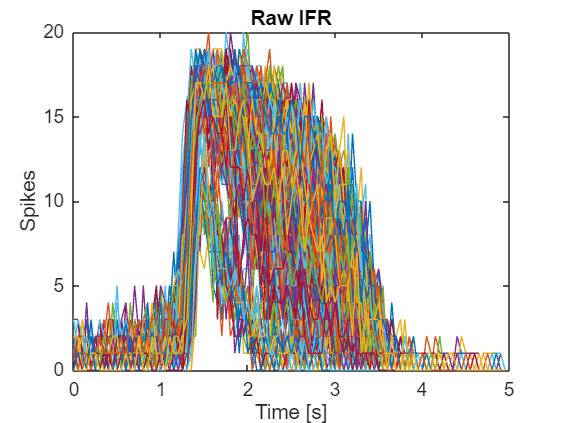

Smoothing_factor = 15

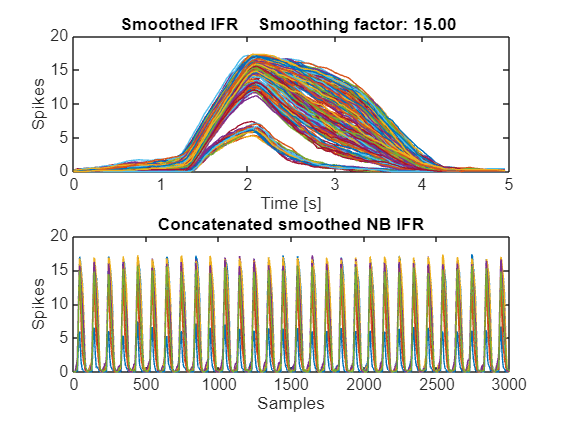





bin_size = 0.05; % [s] 0.005 = 5 [ms]

[NB_IFR, bin_size,window_size] = Get_NB(data,fs,Cumulative,t_vec,step_s,bin_size);

[NB_IFR_smoothed, NB_IFR_smoothed_concatenated] = Smoothed_IFR(NB_IFR, bin_size,window_size,fs);

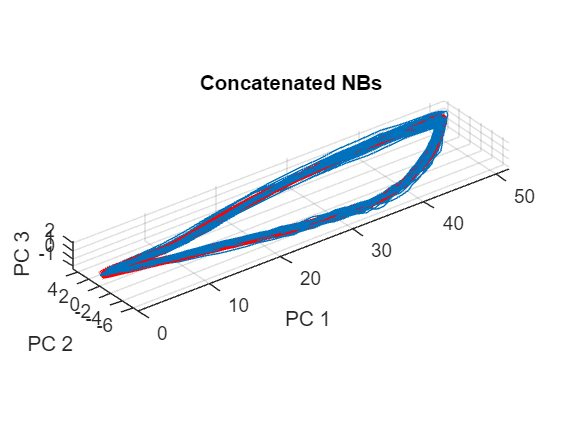



[Variance_explained, Projected_trajectories,Coefficients,NB_IFR_PCA_mean] = get_PCA(NB_IFR_smoothed_concatenated,NB_IFR_smoothed);

Total_variance_explained = 99.6569

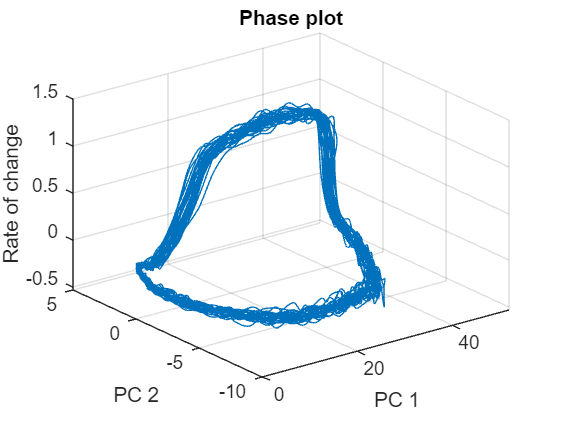


[Velocity_concatenated,Velocity] = Get_Velocities(NB_IFR_smoothed_concatenated,NB_IFR_smoothed);
Draw_Phase_Portrait(Projected_trajectories,Velocity_concatenated,Variance_explained)


% % Export data
% cd 'E:\Rec Linda\Dup15\Batch1\DIV35_5337\20240625_Group_02\Neuronal Dynamics'
% % Write the vector to the CSV file
% writematrix(Variance_explained, 'Variance_explained20.csv'); 
% writematrix(Projected_trajectories, 'Projected_trajectories20.csv');

% cd 'E:\Rec Linda\Dup15\Batch2\DIV35_6867\20240625_Control_00\Neuronal Dynamic'
% writematrix(NB_IFR_PCA_mean, 'Projected_trajectories_means23.csv')
% writematrix(Velocity, 'Velocity_mean23.csv')

bin_size = 0.005; % [s] 0.005 = 5 [ms]

[NB_IFR, bin_size,window_size] = Get_NB(data,fs,Cumulative,t_vec,step_s,bin_size);

Spk_count = Criticality(NB_IFR);


function Spk_count = Criticality(Binned_NB)
 % Binned_NB:  NB binned but NOT smoothed
 % We will evaluate the distribution of spikes within the NB.
 % This measure is highly succeptible to the chosen bin size. Usually 
 % what is done is to evaluate different bin sizes and then select the 
 % optimal one.

 
% Concatenate NB 
% Rows are the variables; columns the samples
Cut_NB = cell(1,length(Binned_NB));
max__ = 0;   
W_s = size(Binned_NB{1},2);
plot_vect = 0:W_s-1;
for j = 1:length(Binned_NB)

    NB = Binned_NB{j};
    NB_summed = sum(NB,1);
    % Cut avalanches: Avalanches are confined within no spikes bins
    Non_zeros = find(NB_summed>0);
    Start = Non_zeros(1)-1;
    End = Non_zeros(end)+1;

    % figure()
    % plot(plot_vect,NB);
    % hold on
    % scatter([Start,End],[5,5],10,'red')
    % hold off
    NB_filtered = NB_summed(Non_zeros);
    dgs = max(NB_filtered);

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

    if max__< max(NB_filtered)
        max__ = max( NB_filtered);
    end

    Cut_NB{j}  = NB_summed(Non_zeros);

end

Spk_count = zeros(1,max__);

for j = 1:length(Binned_NB)
    NB_cut  = Cut_NB{j};

    N_spk = unique(NB_cut);
    for i = 1:length(N_spk)

        Number_spks = length(find(NB_cut == N_spk(i)));

        Spk_count(i) = Spk_count(i) + Number_spks;


    end

end

        




end























function Draw_Phase_Portrait(Projected_trajectories,Velocity_vector,Variance_explained)

    % Take the first two PC, and print the variance explained
    Total_variance_explained = sum(Variance_explained(1:2))


    mean_vel = mean(Velocity_vector,1);

    row_len = 1:length(mean_vel);

    % Upsample
    t_interp = linspace(1, length(mean_vel),length(mean_vel)* 10); % Create 100 evenly spaced time points
    Mean_vel_interp = interp1(row_len, mean_vel, t_interp, 'cubic');

    PC_1 = interp1(row_len, Projected_trajectories(:,1), t_interp, 'cubic');
    PC_2 = interp1(row_len, Projected_trajectories(:,2), t_interp, 'cubic');
    figure()

    % plot3(Projected_trajectories(:,1),Projected_trajectories(:,2),mean_vel)
    plot3(PC_1,PC_2,Mean_vel_interp)

    % To keep the axes scaled appropriately and prevent distortion
    
    
    % You can also add a grid
    grid on;
    
    % To rotate the view interactively
    rotate3d on;

    xlabel('PC 1');
    ylabel('PC 2');
    zlabel('Rate of change');
    title('Phase plot');




end













function Animation(Projected_trajectories,Velocity)











%%% For now we will take just the mean velocity
Mean_vel = mean(Velocity,1);

% Normalize
Mean_vel = Mean_vel/max(Mean_vel);
row_len = 1:length(Mean_vel);

% Upsample
t_interp = linspace(1, length(Mean_vel),length(Mean_vel)* 5); % Create 100 evenly spaced time points
Mean_vel_interp = interp1(row_len, Mean_vel, t_interp, 'cubic');




% Inverse

Mean_vel_inverse = Mean_vel_interp - 0.99; % Avoids divisions per zero

% Extract the First three components
x = Projected_trajectories(:, 1);
y = Projected_trajectories(:, 2);
z = Projected_trajectories(:, 3);

% Upsample

x = interp1(row_len, x, t_interp, 'cubic');

y = interp1(row_len, y, t_interp, 'cubic');

z = interp1(row_len, z, t_interp, 'cubic');


figure;
hold on
view(3); % Imposta la visualizzazione in 3D
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Animazione Traiettoria 3D con Vettore Velocità');
plot3(x, y, z,'LineWidth',0.01);
    


for i = 1:length(t_interp)

    x_p = x(1,i);
    y_p = y(1,i);
    z_p = z(1,i);

    
    scatter3(x_p,y_p,z_p,30,'magenta','filled')
    
    
    pause(0.000000001*Mean_vel_inverse(i));

    drawnow

end



end





function [Velocity,Velocity_mean] = Get_Velocities(NB_IFR_smoothed_concatenated,NB_IFR_smoothed)

% It's aim is to provide informations about how rapidly the culture follows
% the trajectory both in the cultured-pivoted frame and in the PC base.
% It is calculated channel wide (each channel independently) then we will
% map it into the PC space ( with or without it ), It might also be
% interesting to take the same approach of PCA reduction on this vector

% Velocity mean is the mean rate of change during one period of NB across
% all the NBs and the channels
Velocity = zeros(size(NB_IFR_smoothed_concatenated,1),size(NB_IFR_smoothed_concatenated,2));
    for sample = 1:size(NB_IFR_smoothed_concatenated,2)-1

        Velocity(:,sample+1) = NB_IFR_smoothed_concatenated(:,sample+1) - NB_IFR_smoothed_concatenated(:,sample);

    end


Velocity_mean = zeros(size(NB_IFR_smoothed{1},1),size(NB_IFR_smoothed{1},2),length(NB_IFR_smoothed));


for k = 1:length(NB_IFR_smoothed)

    NB_IFR_PCA_= NB_IFR_smoothed{k};
    
    for sample = 1:size(NB_IFR_PCA_,2)-1

        Velocity_mean(:,sample+1,k) = NB_IFR_PCA_(:,sample+1) - NB_IFR_PCA_(:,sample);

    end


end



Velocity_mean = mean(Velocity_mean,3);
Velocity_mean = mean(Velocity_mean,1);
end


function [Variance_explained, Projected_trajectories,Coefficients,NB_IFR_PCA_mean]= get_PCA(NB_IFR_smoothed_concatenated,NB_IFR_smoothed)


    % PCA(X) The rows of X correspond to observations, and the columns
    % correspond to variables. This is required to extract the coefficients.
    % However if we give as input the trnasposed version, the putput is
    % original vecotor but transformed / projected in the new space.
    
    % FInd the set of ceofficients
    % Principal component coefficients, returned as a p-by-k numeric matrix, where p=size(X,2). If X is a tall array, coeff is a p-by-p numeric matrix. 
    
    % The Value of Each Coefficient: The value at coeff(i, j) represents the weight or contribution of the i-th original variable to the j-th principal component.
    % Thus to project a datatset into the PCA-based space we have to do a
    % matrix 

    % RETURNS
    % Variance_explained: Percentage of the total variance explained by each principal component, returned as a numeric column vector of length k.
    % Projected_trajectories: Data projected onto the new space 


   


    NB_IFR_smoothed_concatenated_PCA = NB_IFR_smoothed_concatenated';
    [Coefficients,~,~,~,Variance_explained,~]= pca(NB_IFR_smoothed_concatenated_PCA);
    % 
    
    
    %%% Obtain the mean traces
    
    
    NB_IFR_PCA_mean_ = zeros(size(NB_IFR_smoothed{1},1),size(NB_IFR_smoothed{1},2),length(NB_IFR_smoothed));
    for k = 1:length(NB_IFR_smoothed)
        NB_IFR_PCA_= NB_IFR_smoothed{k};
        proj = NB_IFR_PCA_' * Coefficients;
        NB_IFR_PCA_mean_(:,:,k) = proj';
    
    end
    
    NB_IFR_PCA_mean = mean(NB_IFR_PCA_mean_,3)';
    
    
    
    
    % Project the data
    Projected_trajectories = NB_IFR_smoothed_concatenated_PCA * Coefficients;
    
    
    figure()


    % Interpolate
    row_len = 1:size(Projected_trajectories,1);

    

    % Extract the First three components
    x = Projected_trajectories(:, 1);
    y = Projected_trajectories(:, 2);
    z = Projected_trajectories(:, 3);
    
    x_m = NB_IFR_PCA_mean(:,1);
    y_m = NB_IFR_PCA_mean(:,2);
    z_m = NB_IFR_PCA_mean(:,3);
    
    % Use the plot3 function to plot the lines connecting the points
    plot3(x, y, z);
    
    hold on
    
    plot3(x_m, y_m, z_m,'LineWidth',4.5,'Color','red');
    
    
    hold off
    % Add labels and title for clarity
    xlabel('PC 1');
    ylabel('PC 2');
    zlabel('PC 3');
    title('Concatenated NBs');
    
    % You can customize the appearance of the lines
    % For example, change the color, line style, and marker:
    % plot3(x, y, z, 'r-o'); % Red solid line with circle markers at each point
    % plot3(x, y, z, 'b--'); % Blue dashed line
    
    % To keep the axes scaled appropriately and prevent distortion
    axis equal;
    
    % You can also add a grid
    grid on;
    
    % To rotate the view interactively
    rotate3d on;

end








function [NB_IFR_smoothed,NB_IFR_smoothed_concatenated] = Smoothed_IFR(NB_IFR, bin_size,window_size,fs)
% The function takes the raw istantaneous firing rates of the NB-centered
% windows and returns the concatenated and smoothed NB's IFR.





    T_vec_NB = 0:bin_size:window_size-1;
    
    
    
    figure()
    
    for j = 1:size(NB_IFR,1)
        NB_IFR__ = NB_IFR{j};
        for i = 1:size(NB_IFR{1},1)
            channel = NB_IFR__(i,:);
            plot(T_vec_NB/fs,channel);
    
    
            hold on
        
        end
        
    end
    title('Raw IFR')
    xlabel('Time [s]')
    ylabel('Spikes')
    hold off
    
    
    
    % alpha can be added in the gaussian function; resulating in a standard deviation of (N−1)/2α
    Samples_per_window  = length(T_vec_NB);
    L = 0.0015 * fs; % Width [s] converted in samples
    
    % Smoothing_factor captures the persentage of the windowed NB that is
    % smoothed at each step.
    Smoothing_factor = L/Samples_per_window*100
    % w = gausswin(L)
    windowSize = L; 
    b = (1/windowSize)*ones(1,windowSize);
    NB_IFR_smoothed = NB_IFR;
    NB_IFR_smoothed_concatenated = zeros(size(NB_IFR{1},1),size(NB_IFR,1) * Samples_per_window);
    n = 0;
    

    
    for j = 1:size(NB_IFR,1)
        NB_IFR__ = NB_IFR{j};

        % Channel wise
        for i = 1:size(NB_IFR{1},1)
            channel = NB_IFR__(i,:);




            NB_IFR_smoothed{j}(i,:) = filter(b,1,channel);




            NB_IFR_smoothed_concatenated(i,n*Samples_per_window +1 : (n+1)* Samples_per_window) = filter(b,1,channel);

    
        end
        n = n+1;
        
    end
    
    
    
    
    
    
    figure()
    subplot(2,1,1)
    for j = 1:size(NB_IFR,1)
        NB_IFR__ = NB_IFR_smoothed{j};
        for i = 1:size(NB_IFR{1},1)
            channel = NB_IFR__(i,:);
            plot(T_vec_NB/fs,channel);
    
    
            hold on
        
        end
        
    end
    hold off
    title(sprintf('Smoothed IFR    Smoothing factor: %.2f %', Smoothing_factor));
    xlabel('Time [s]')
    ylabel('Spikes')

    subplot(2,1,2)
    Ch = 3;
    T_Vec_conc = 0:size(NB_IFR_smoothed_concatenated,2)-1;
    plot(T_Vec_conc,NB_IFR_smoothed_concatenated);

    hold off
    title(sprintf('Concatenated smoothed NB IFR'));
    xlabel('Samples')
    ylabel('Spikes')
end





function [NB_IFR, bin_size,window_size] = Get_NB(data,fs,Cumulative,t_vec,step_s,bin_size)

        % bin_size is expressed in seconds
        % t_vec: downsampled time vector for the smoothing


        % construct the windowed that will be centered at the NB's peak
        pre_w = 1.5; % Pre samples [s]
        post_w = 3.5; % post samples [s]
        


        % Scale

        pre_w = pre_w*fs;
        post_w = post_w*fs;
        bin_size = bin_size*fs; % [samples]

        % Define the window size for calculatin the IFR
        window_size = pre_w + post_w; % [samples]
        Num_bins = floor(window_size/bin_size);


        

        % Isolate the NB timings (peaks location).
        Mean_IFR = mean(Cumulative); 
        STD_IFR = std(Cumulative);
        [A,idx] = findpeaks(Cumulative,"MinPeakHeight",Mean_IFR+STD_IFR,MinPeakDistance=3 * fs / step_s);
        NB_T = t_vec(idx);

        NB_IFR = cell(length(NB_T),1); % Location of the 
        
        for NB = 1:length(NB_T)

            Binned_NB = zeros(length(data),Num_bins); % Rows = Ch;    Columns: Bin
            
            Lower_bound = NB_T(NB) - pre_w;
            Upper_bound = NB_T(NB) + post_w;


            % Extract per each channel the spikes within the NB window
            
            for Ch = 1 : length(data)
                
                % Extract channel's spk train
                data_ = data{Ch};
                
                % Extract channel's spks within the NB
                within_range = (data_ >= Lower_bound) & (data_ <= Upper_bound );

                % Define the spike times of the events within the window
                spikes_time = data_(within_range);

                % Extract the IFR across the binned signal
                

                for bin = 1:Num_bins-1

                    % Define the start and stop timings counturing the bin.
                    % Lower_bound is needed to correctly align the sliding
                    % window with the NB of interest
                    start_idx = Lower_bound + bin*bin_size + 1;
                    stop_idx = Lower_bound + (bin+1)*bin_size;

                    % Extract spikes within the window (inclusive of the
                    % boundaries)
                    within_range = (data_ >= start_idx) & (data_ <= stop_idx );

                    % Count
                    Number_spks = sum(within_range);
                    
                    % Load the # of spikes occuring in the Ch channel and
                    % wihtin the specific bin.
                    Binned_NB(Ch,bin) = Number_spks;

                end

            end

            % Load everything in the main variable
            NB_IFR{NB,1} = Binned_NB;

        end
end





% Smoothing function

function [Cumulative,t_vec,step_size] =Rect_window(fs,w_size, overlap,x,T_max)

% # of windows: defining x_s as length of x
%  N_W = [(x_s - w_size)/(w_size - overlap)] +1
% we floor this approx. number because we are not interested in handling
% partial windows.
% w_size [ms]
% overlap [ms]
% x is the rasterplot compressed in a cell.
% MFR
w_size = w_size * fs;
overlap = overlap * fs;

% N_W = floor(( (T_max - w_size)/(w_size - overlap)) +1);
step_size = w_size - overlap;
t_vec = 0:step_size:T_max;
Cumulative = zeros(length(t_vec),1);
start_index =1;
idx = 1;
while start_index + w_size-1 <= T_max
    Temp_cum = 0;
    for ch = 1:length(x)
        data_ = x{ch};

        within_range = (data_ >= start_index) & (data_ <= start_index + w_size-1 );

        count = sum(within_range);

        Temp_cum = Temp_cum + count;

    end

    Cumulative(idx,1) = Temp_cum/w_size;
        
        






    start_index = start_index + step_size;
    idx = idx + 1;

    end
end

